#                      Blind Source Separation

##                                           Project-Approach:2

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1402/03/15                


clear; clc; close all;
% Load sample Data:
Data_Subject   = load("dataset\subj_1.mat");
Data_Subject_i = Data_Subject.data; 

## Data Tyding:

fs = 2400; % Given sampling frequency

TrainData_class1 = Data_Subject_i{1,1};
TrainData_class2 = Data_Subject_i{1,2};
TrainData_class3 = Data_Subject_i{1,3};
TrainData_class4 = Data_Subject_i{1,4};

% Removing Data Bias:
Num_of_Rows  = length(TrainData_class1(:,1,1));
Num_of_Cols  = length(TrainData_class1(1,:,1));
Num_of_Pages = length(TrainData_class1(1,1,:));

TrainData_class1 = TrainData_class1 - repmat( mean(TrainData_class1, 2) ,1,Num_of_Cols) ;
TrainData_class2 = TrainData_class2 - repmat( mean(TrainData_class2, 2) ,1,Num_of_Cols) ;
TrainData_class3 = TrainData_class3 - repmat( mean(TrainData_class3, 2) ,1,Num_of_Cols) ;
TrainData_class4 = TrainData_class4 - repmat( mean(TrainData_class4, 2) ,1,Num_of_Cols) ;
% Distinguish Test & Train:
Test_IDX = [randi(size(TrainData_class1,3)) , randi(size(TrainData_class2,3)) ,...
            randi(size(TrainData_class3,3)),  randi(size(TrainData_class4,3)) ];

Test_class1 = TrainData_class1(:,:,Test_IDX(1));
Test_class2 = TrainData_class2(:,:,Test_IDX(2));
Test_class3 = TrainData_class3(:,:,Test_IDX(3));
Test_class4 = TrainData_class4(:,:,Test_IDX(4));
% Removing Test Data from Train Dataset:
TrainData_class1(:,:,Test_IDX(1)) = [];
TrainData_class2(:,:,Test_IDX(2)) = [];
TrainData_class3(:,:,Test_IDX(3)) = [];
TrainData_class4(:,:,Test_IDX(4)) = [];

% Changing Mobility factor of class 4 into 0:
TrainData_class4(end,:,:) = 0;
% Remove Channel 64 which is the  origin of recording:
TrainData_class1(end,:,:) = [];
TrainData_class2(end,:,:) = [];
TrainData_class3(end,:,:) = [];
TrainData_class4(end,:,:) = [];

% Remove Final Row from Test Data (row 64):
Test_class1(end,:,:) = [];
Test_class2(end,:,:) = [];
Test_class3(end,:,:) = [];
Test_class4(end,:,:) = [];


## Calc Covariance+ Calc Wcsp + Calc WLDA:

Let's decide based on a Model which is like a Decision Tree!

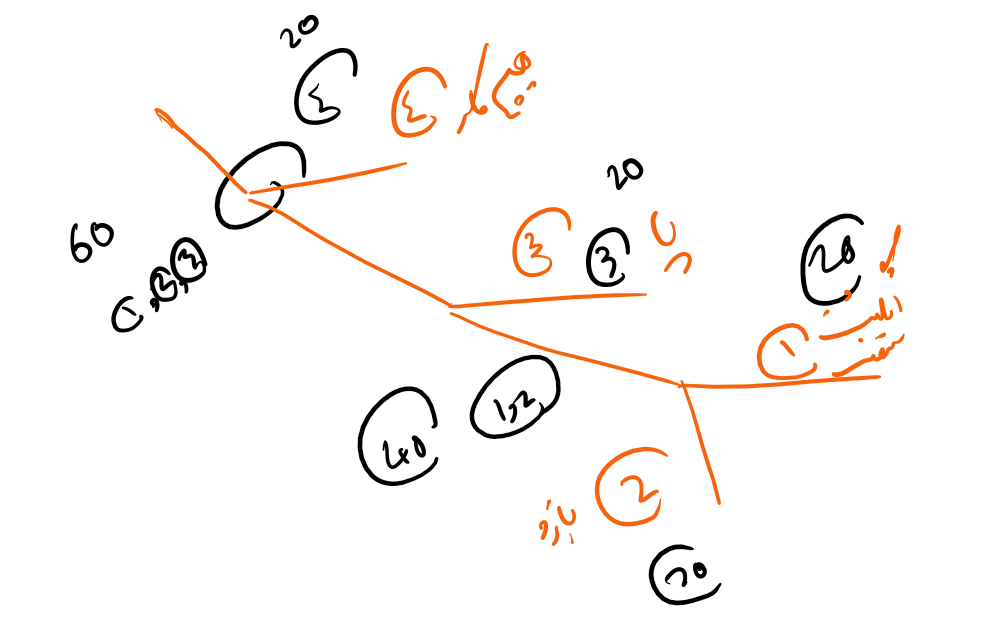

% Covariance Calc:
R_class_1_Sum = R_SUM_Calc(TrainData_class1);
R_class_2_Sum = R_SUM_Calc(TrainData_class2);
R_class_3_Sum = R_SUM_Calc(TrainData_class3);
R_class_4_Sum = R_SUM_Calc(TrainData_class4);

TrainData_class123 = cat(3,TrainData_class1, TrainData_class2 ,  TrainData_class3);
R_class_123_Sum = R_SUM_Calc(TrainData_class123);

TrainData_class12 = cat(3,TrainData_class1, TrainData_class2 );
R_class_12_Sum = R_SUM_Calc(TrainData_class12);



% Now Let's Map Data properly based on The Decision Tree Model:
Classifier_1_for4       =  CSP_Filter_W(R_class_4_Sum,R_class_123_Sum);
Classifier_2_for3       =  CSP_Filter_W(R_class_3_Sum,R_class_12_Sum);
Classifier_3_Final      =  CSP_Filter_W(R_class_1_Sum,R_class_2_Sum);


% Map Data:
Z_Class4_vs_123 = tensorprod(Classifier_1_for4',TrainData_class4,2,1);
Z_Class123_vs_4 = tensorprod(Classifier_1_for4',TrainData_class123,2,1);


Z_Class3_vs_12 = tensorprod(Classifier_2_for3',TrainData_class3,2,1);
Z_Class12_vs_3 = tensorprod(Classifier_2_for3',TrainData_class12,2,1);

Z_Class1_vs_2 = tensorprod(Classifier_3_Final',TrainData_class1,2,1);
Z_Class2_vs_1 = tensorprod(Classifier_3_Final',TrainData_class2,2,1);

## Calculate LDA (Linear Dsicriminator Analysis) Classifier Weights:

[W_LDA_4_vs_123  , C_4_vs_123  , New_Mean_Class_4_vs_123 , New_Mean_Class_123_vs_4 ] = LDA_Classifier(Z_Class4_vs_123 , Z_Class123_vs_4);
[W_LDA_3_vs_12   , C_3_vs_12   , New_Mean_Class_3_vs_12  , New_Mean_Class_12_vs_3  ] = LDA_Classifier(Z_Class3_vs_12 , Z_Class12_vs_3);
[W_LDA_1_vs_2    , C_1_vs_2    , New_Mean_Class_1_vs_2   , New_Mean_Class2_vs_1    ] = LDA_Classifier(Z_Class1_vs_2 , Z_Class2_vs_1);

## Accuracy Calculation:

New_Data_Projected_LDA_Class_4_vs_123 = tensorprod( W_LDA_4_vs_123, squeeze(var(Z_Class4_vs_123,0,2)) , 1,1 );
New_Data_Projected_LDA_Class_123_vs_4 = tensorprod( W_LDA_4_vs_123, squeeze(var(Z_Class123_vs_4,0,2)) , 1,1 );

Num_of_Trials_4   = size(Z_Class4_vs_123,3);
Num_of_Trials_123 = size(Z_Class123_vs_4,3);

Cntr4_vs_123 = 0;
for i=1:Num_of_Trials_4
    Data_Var_Check_Class_4_vs_123 =  (New_Data_Projected_LDA_Class_4_vs_123(1,i)) ;
    if( C_4_vs_123 > Data_Var_Check_Class_4_vs_123   ) % Belongs to Class 4
        Cntr4_vs_123 = Cntr4_vs_123+1;
    end
end

Cntr_123_vs_4 = 0;
for i=1:Num_of_Trials_123
    Data_Var_Check_Class_123_vs_4 =  (New_Data_Projected_LDA_Class_123_vs_4(1,i)) ;
    if( C_4_vs_123 < Data_Var_Check_Class_123_vs_4   ) % Belongs to Class 123
        Cntr_123_vs_4 = Cntr_123_vs_4+1;
    end
end



Accuracy_Train_Class_4 = Cntr4_vs_123/Num_of_Trials_4*100;
disp("Class 4 Accuracy is: "+Accuracy_Train_Class_4+" %")

Accuracy_Train_Class_123 = Cntr_123_vs_4/Num_of_Trials_123*100;
disp("Class 123 Accuracy is: "+Accuracy_Train_Class_123+" %")



## Class 12 vs 3


New_Data_Projected_LDA_Class_3_vs_12 = tensorprod( W_LDA_3_vs_12, squeeze(var(Z_Class3_vs_12,0,2)) , 1,1 );
New_Data_Projected_LDA_Class_12_vs_3 = tensorprod( W_LDA_3_vs_12, squeeze(var(Z_Class12_vs_3,0,2)) , 1,1 );

Num_of_Trials_3   = size(Z_Class3_vs_12,3);
Num_of_Trials_12 = size(Z_Class12_vs_3,3);

Cntr3_vs_12 = 0;
for i=1:Num_of_Trials_3
    Data_Var_Check_Class_3_vs_12 =  (New_Data_Projected_LDA_Class_3_vs_12(1,i)) ;
    if( C_3_vs_12 < Data_Var_Check_Class_3_vs_12   ) % Belongs to Class 3
        Cntr3_vs_12 = Cntr3_vs_12+1;
    end
end

Cntr_12_vs_3 = 0;
for i=1:Num_of_Trials_12
    Data_Var_Check_Class_12_vs_3 =  (New_Data_Projected_LDA_Class_12_vs_3(1,i)) ;
    if( C_4_vs_123 > Data_Var_Check_Class_12_vs_3   ) % Belongs to Class 12
        Cntr_12_vs_3 = Cntr_12_vs_3+1;
    end
end


Accuracy_Train_Class_3 = Cntr3_vs_12/Num_of_Trials_3*100;
disp("Class 3 Accuracy is: "+Accuracy_Train_Class_3+" %")

Accuracy_Train_Class_12 = Cntr_12_vs_3/Num_of_Trials_12*100;
disp("Class 12 Accuracy is: "+Accuracy_Train_Class_12+" %")

## Class 1 vs 2

New_Data_Projected_LDA_Class_1_vs_2 = tensorprod( W_LDA_1_vs_2, squeeze(var(Z_Class1_vs_2,0,2)) , 1,1 );
New_Data_Projected_LDA_Class_2_vs_1 = tensorprod( W_LDA_1_vs_2, squeeze(var(Z_Class2_vs_1,0,2)) , 1,1 );

Num_of_Trials_1   = size(Z_Class1_vs_2,3);
Num_of_Trials_2 = size(Z_Class2_vs_1,3);

Cntr1_vs_2 = 0;
for i=1:Num_of_Trials_1
    Data_Var_Check_Class_1_vs_2 =  (New_Data_Projected_LDA_Class_1_vs_2(1,i)) ;
    if( C_1_vs_2 < Data_Var_Check_Class_1_vs_2   ) % Belongs to Class 1
        Cntr1_vs_2 = Cntr1_vs_2+1;
    end
end

Cntr_2_vs_1 = 0;
for i=1:Num_of_Trials_2
    Data_Var_Check_Class_2_vs_1 =  (New_Data_Projected_LDA_Class_2_vs_1(1,i)) ;
    if( C_1_vs_2 > Data_Var_Check_Class_2_vs_1   ) % Belongs to Class 2
        Cntr_2_vs_1 = Cntr_2_vs_1+1;
    end
end


Accuracy_Train_Class_1 = Cntr1_vs_2/Num_of_Trials_1*100;
disp("Class 1 Accuracy is: "+Accuracy_Train_Class_1+" %")
Accuracy_Train_Class_2 = Cntr_2_vs_1/Num_of_Trials_2*100;
disp("Class 2 Accuracy is: "+Accuracy_Train_Class_2+" %")

## Test Accuracy:

W_CSP = { Classifier_1_for4 , Classifier_2_for3 , Classifier_3_Final     };
W_LDA = { W_LDA_4_vs_123    , W_LDA_3_vs_12     , W_LDA_1_vs_2  };
C     = { C_4_vs_123        , C_3_vs_12         , C_1_vs_2};

Label_Pred_1 = Predictor(Test_class1 , W_CSP , W_LDA , C);
Label_Pred_2 = Predictor(Test_class2 , W_CSP , W_LDA , C);
Label_Pred_3 = Predictor(Test_class3 , W_CSP , W_LDA , C);
Label_Pred_4 = Predictor(Test_class4 , W_CSP , W_LDA , C);



## Final Modules:

Num_of_Iters = 100;
Conf_Matrixes = cell(1,Num_of_Iters);
Final_Conf = zeros(size(Data_Subject_i,2));

% Channel Selection:
channels1 = 1:63; channels2 = 1:63; channels3 = [1:10,22,23,25,26,27,30,32,50,51,55,56,58,59,60,62];  % 22,23,25,26,27,30,32,50,51,55,56,58,59,60,62, 
Channels_Cell = {channels1 ,channels2 ,channels3 };
% Filter Selection:
m1 = 13;  m2 = 21; m3 = 11;  
Filters_WCSP  = [m1,m2,m3];

for i=1:Num_of_Iters
    [Data_Train , Data_Test] = Test_Train_Dist(Data_Subject_i);
    [W_CSP , Z ]  = Trainer_W_CSP(Data_Train,Channels_Cell,Filters_WCSP);
    [W_LDA , C , Means] = Trainer_LDA(Z);
    Predicted = zeros(1,size(Data_Test,2));
    for j=1:size(Data_Test,2)
               
               Predicted(1,j)   =  Tester(W_LDA, W_CSP , C,Means ,  Data_Test{1,j},Channels_Cell,Filters_WCSP);
    end
    Conf_Matrixes{1,i} = confusionmat([1,2,3,4], Predicted)  ;  
    Final_Conf = Final_Conf + Conf_Matrixes{1,i};
%     pause(0.01);
    clc;
    disp("Progress:  %"+ i/Num_of_Iters*100 );
    fprintf('\b\b\b\b\b\b%3d%% [%s]', round(i / Num_of_Iters * 100), repmat('=', 1, round(i/Num_of_Iters*100)));
    % waitbar(round(i/Num_of_Iters));
   
end


disp("Final Confusion Matrix equals to: ")
disp(Final_Conf/Num_of_Iters);
Accuracy_Test_Class_1 = Final_Conf(1,1)/Num_of_Iters*100;
Accuracy_Test_Class_2 = Final_Conf(2,2)/Num_of_Iters*100;
Accuracy_Test_Class_3 = Final_Conf(3,3)/Num_of_Iters*100;
Accuracy_Test_Class_4 = Final_Conf(4,4)/Num_of_Iters*100;
disp("Accuracies are: 1: "+ Accuracy_Test_Class_1 +"% 2: "+ Accuracy_Test_Class_2 +"% 3: "+ ...
                            Accuracy_Test_Class_3  +"% 4: "+Accuracy_Test_Class_4+" %")
beep;

## Functions:

function [W_LDA , C , Means] = Trainer_LDA(Z)

    Z_Class4_vs_123 = Z{1,1};
    Z_Class123_vs_4 = Z{1,2};
    Z_Class3_vs_12 = Z{1,3};
    Z_Class12_vs_3 = Z{1,4};
    Z_Class1_vs_2 = Z{1,5};
    Z_Class2_vs_1 = Z{1,6};
    
    
    [W_LDA_4_vs_123  , C_4_vs_123  , New_Mean_Class_4_vs_123 , New_Mean_Class_123_vs_4 ] = LDA_Classifier(Z_Class4_vs_123 , Z_Class123_vs_4);
    [W_LDA_3_vs_12   , C_3_vs_12   , New_Mean_Class_3_vs_12  , New_Mean_Class_12_vs_3  ] = LDA_Classifier(Z_Class3_vs_12 , Z_Class12_vs_3);
    [W_LDA_1_vs_2    , C_1_vs_2    , New_Mean_Class_1_vs_2   , New_Mean_Class2_vs_1    ] = LDA_Classifier(Z_Class1_vs_2 , Z_Class2_vs_1);
    
    W_LDA = {W_LDA_4_vs_123 ,W_LDA_3_vs_12,W_LDA_1_vs_2 };
    C     = {C_4_vs_123 , C_3_vs_12 , C_1_vs_2};
    
    Means = { [New_Mean_Class_4_vs_123 , New_Mean_Class_123_vs_4 ], ...
              [New_Mean_Class_3_vs_12 ,New_Mean_Class_12_vs_3 ], ...
              [New_Mean_Class_1_vs_2 , New_Mean_Class2_vs_1]  };

end

function filtered_matrix = Freq_filter(Input_Matrix,L_BW,H_BW)
    % Get dimensions of input matrix
    % [M, T, N] = size(Input_Matrix);
    % Initialize filtered matrix
    % filtered_matrix = zeros(M, T, N);
    % Apply filter to each channel and trial
%     for m = 1:M
%         for n = 1:N
%             % Filter the time signal using the Butterworth filter
%             filtered_matrix(m, :, n) = filtfilt(b, a, Input_Matrix(m, :, n));
%         end
%     end
    Data1_f = fftshift(fft(Input_Matrix, [], 2), 2);
%     figure
%     plot(f, abs(Data1_f(1,:,1)))
%     grid on
%     xlabel('freq (Hz)')
    fs   = 2400;
    Nfft = 7200;
    f    = -fs/2 : 1/Nfft*fs : fs/2 - 1/Nfft;
    Data1_f(f > H_BW | f < -H_BW) = 0;
    Data1_f(f < L_BW & f > -L_BW) = 0;
    filtered_matrix = ifft(ifftshift(Data1_f, 2), [], 2);
end

function filtered_matrix = Data_Freq_Filter(Data,filter_CLass)
    % fs = 2400; % 2400Hz
    % Define filter parameters     % Create Butterworth filter
%     low_freq = 10;  high_freq = 40;    order = 30;  
%     [b1, a1] = butter(order, [low_freq, high_freq] / (fs/2), 'bandpass');
% 
%     low_freq = 10;  high_freq = 20;    order = 30;  
%     [b2, a2] = butter(order, [low_freq, high_freq] / (fs/2), 'bandpass');
% 
%     low_freq = 0.01;  high_freq = 4;    order = 90;  
%     [b3, a3] = butter(order, [low_freq, high_freq] / (fs/2), 'bandpass');


        Input_Matrix = Data;
        if (filter_CLass==1)
            L_BW1 = 10;  H_BW1 = 40; 
            filtered_matrix = Freq_filter(Input_Matrix,L_BW1,H_BW1);
        elseif (filter_CLass==2)
            L_BW2 = 10;  H_BW2 = 20;
            filtered_matrix = Freq_filter(Input_Matrix,L_BW2,H_BW2);
        elseif (filter_CLass==3)
            L_BW3 = 0.01;  H_BW3 = 4;
            filtered_matrix = Freq_filter(Input_Matrix,L_BW3,H_BW3);
        end


end


function [Data_Train , Data_Test] = Test_Train_Dist(Data_Subject_i)


    TrainData_class1 = Data_Subject_i{1,1};
    TrainData_class2 = Data_Subject_i{1,2};
    TrainData_class3 = Data_Subject_i{1,3};
    TrainData_class4 = Data_Subject_i{1,4};
    
    % Removing Data Bias:
    % Num_of_Rows  = length(TrainData_class1(:,1,1));
    Num_of_Cols  = length(TrainData_class1(1,:,1));
    % Num_of_Pages = length(TrainData_class1(1,1,:));
    
    TrainData_class1 = TrainData_class1 - repmat( mean(TrainData_class1, 2) ,1,Num_of_Cols) ;
    TrainData_class2 = TrainData_class2 - repmat( mean(TrainData_class2, 2) ,1,Num_of_Cols) ;
    TrainData_class3 = TrainData_class3 - repmat( mean(TrainData_class3, 2) ,1,Num_of_Cols) ;
    TrainData_class4 = TrainData_class4 - repmat( mean(TrainData_class4, 2) ,1,Num_of_Cols) ;
    % Distinguish Test & Train:
    Test_IDX = [randi(size(TrainData_class1,3)) , randi(size(TrainData_class2,3)) ,...
                randi(size(TrainData_class3,3)),  randi(size(TrainData_class4,3)) ];
    
    Test_class1 = TrainData_class1(:,:,Test_IDX(1));
    Test_class2 = TrainData_class2(:,:,Test_IDX(2));
    Test_class3 = TrainData_class3(:,:,Test_IDX(3));
    Test_class4 = TrainData_class4(:,:,Test_IDX(4));
    % Removing Test Data from Train Dataset:
    TrainData_class1(:,:,Test_IDX(1)) = [];
    TrainData_class2(:,:,Test_IDX(2)) = [];
    TrainData_class3(:,:,Test_IDX(3)) = [];
    TrainData_class4(:,:,Test_IDX(4)) = [];
    
    % Changing Mobility factor of class 4 into 0:
    TrainData_class4(end,:,:) = 0;
    % Remove Channel 64 which is the  origin of recording:
    TrainData_class1(end,:,:) = [];
    TrainData_class2(end,:,:) = [];
    TrainData_class3(end,:,:) = [];
    TrainData_class4(end,:,:) = [];
    
    % Remove Final Row from Test Data (row 64):
    Test_class1(end,:,:) = [];
    Test_class2(end,:,:) = [];
    Test_class3(end,:,:) = [];
    Test_class4(end,:,:) = [];
    
    
    Data_Train = {TrainData_class1, TrainData_class2, TrainData_class3 , TrainData_class4};
    Data_Test  = {Test_class1 , Test_class2 , Test_class3 , Test_class4}; 
end

function Predicted   =  Tester(W_LDA, W_CSP , C,Means , Data_Test, Channels_Cell, Filters_WCSP )
    
    Predicted = Predictor(Data_Test, W_CSP , W_LDA , C, Means , Channels_Cell , Filters_WCSP );

end

function [W_CSP , Z ]  = Trainer_W_CSP(Data,Channels_Cell,Filters_WCSP)


    TrainData_class1 = Data{1,1};
    TrainData_class2 = Data{1,2};
    TrainData_class3 = Data{1,3};
    TrainData_class4 = Data{1,4};
    
    % Data_Filtered = Data_Freq_Filter(Data,filter_CLass)
    % Channel Selection
    channels1  = Channels_Cell{1,1} ; channels2  = Channels_Cell{1,2} ; channels3  = Channels_Cell{1,3} ;
    % Filter Selection:
    m1 = Filters_WCSP(1,1); m2 = Filters_WCSP(1,2); m3 = Filters_WCSP(1,3);
    
    % Covariance Calc:
%     R_class_1_Sum = R_SUM_Calc(TrainData_class1);
%     R_class_2_Sum = R_SUM_Calc(TrainData_class2);
%     R_class_3_Sum = R_SUM_Calc(TrainData_class3);
%     R_class_4_Sum = R_SUM_Calc(TrainData_class4);
    
    TrainData_class123 = cat(3,TrainData_class1, TrainData_class2 ,  TrainData_class3);
%     R_class_123_Sum = R_SUM_Calc(TrainData_class123);
    
    TrainData_class12 = cat(3,TrainData_class1, TrainData_class2 );
%     R_class_12_Sum = R_SUM_Calc(TrainData_class12);
    
    
    
    % Now Let's Map Data properly based on The Decision Tree Model:
    % Classifier_1_for4       =  CSP_Filter_W(R_class_4_Sum,R_class_123_Sum);
%     Classifier_2_for3       =  CSP_Filter_W(R_class_3_Sum,R_class_12_Sum);
%     Classifier_3_Final      =  CSP_Filter_W(R_class_1_Sum,R_class_2_Sum);

    % Frequency Filtering: 
    TrainData_class4_Filtered   = Data_Freq_Filter(TrainData_class4,1); 
    TrainData_class123_Filtered = Data_Freq_Filter(TrainData_class123,1);

    TrainData_class3_Filtered  = Data_Freq_Filter(TrainData_class3,2); 
    TrainData_class12_Filtered = Data_Freq_Filter(TrainData_class12,2);

    TrainData_class2_Filtered = Data_Freq_Filter(TrainData_class2,3); 
    TrainData_class1_Filtered = Data_Freq_Filter(TrainData_class1,3);

    [Classifier_1_for4  , Z_Class4_vs_123  ,  Z_Class123_vs_4  ]  = Filter_CSP(TrainData_class4_Filtered(channels1,:,:) , TrainData_class123_Filtered(channels1,:,:));
    [Classifier_2_for3  , Z_Class3_vs_12   ,  Z_Class12_vs_3   ]  = Filter_CSP(TrainData_class3_Filtered(channels2,:,:) , TrainData_class12_Filtered(channels2,:,:));
    [Classifier_3_Final , Z_Class2_vs_1    ,  Z_Class1_vs_2    ]  = Filter_CSP(TrainData_class2_Filtered(channels3,:,:) , TrainData_class1_Filtered(channels3,:,:));
    % Map Data:
    % Z_Class4_vs_123 = tensorprod(Classifier_1_for4',TrainData_class4,2,1);
    % Z_Class123_vs_4 = tensorprod(Classifier_1_for4',TrainData_class123,2,1);
    
    
%     Z_Class3_vs_12 = tensorprod(Classifier_2_for3',TrainData_class3,2,1);
%     Z_Class12_vs_3 = tensorprod(Classifier_2_for3',TrainData_class12,2,1);
%     
%     Z_Class1_vs_2 = tensorprod(Classifier_3_Final',TrainData_class1,2,1);
%     Z_Class2_vs_1 = tensorprod(Classifier_3_Final',TrainData_class2,2,1);
    
    W_CSP = {Classifier_1_for4(:, [1:m1, end-m1+1:end] ) , ...
             Classifier_2_for3(:,[1:m2, end-m2+1:end]) , ...
             Classifier_3_Final(:,[1:m3, end-m3+1:end]) };

    Z = { Z_Class4_vs_123([1:m1, end-m1+1:end],:,:),Z_Class123_vs_4([1:m1, end-m1+1:end],:,:) ...
        , Z_Class3_vs_12([1:m2, end-m2+1:end],:,:),Z_Class12_vs_3([1:m2, end-m2+1:end],:,:)...
        , Z_Class1_vs_2([1:m3, end-m3+1:end],:,:), Z_Class2_vs_1([1:m3, end-m3+1:end],:,:)};


end

function [Classifier , Z_data1 , Z_data2  ] = Filter_CSP(data1 , data2)

    % Covariance Calc:
    R_class_1_Sum = R_SUM_Calc(data1);
    R_class_2_Sum = R_SUM_Calc(data2);
    
    % Now Let's Map Data properly based on The Decision Tree Model:
    Classifier       =  CSP_Filter_W(R_class_1_Sum,R_class_2_Sum);
    % Map Data:
    Z_data1 = tensorprod(Classifier',data1,2,1);
    Z_data2 = tensorprod(Classifier',data2,2,1);
    
    

end

 
function R_class_i_Sum = R_SUM_Calc(Data)
    R_class_i_Sum = zeros(size(Data,1)); % M*M symmetric Matrix; M is number of channels
    R_class_i = cell(size(Data,3),1) ;

    for i=1:size(Data,3) % for number of trials
        R_class_i{i,1} = Data(:,:,i)*Data(:,:,i)';
        R_class_i_Sum = R_class_i{i,1} + R_class_i_Sum ;
    end
    R_class_i_Sum = R_class_i_Sum /size(Data,3) ; % Average based on Number of Trials

end

function Mapped_CSP = Mapper_CSP(data,W_CSP)
   Mapped_CSP =  tensorprod(W_CSP',data,2,1);
end

function Mapped_LDA = Mapper_LDA(data,W_LDA)
    Mapped_LDA = tensorprod( W_LDA, squeeze(var(data,0,2)) , 1,1 ); % Extract the feature and then Mapp with LDA
end

function W_CSP = CSP_Filter_W(R1,R2)

    % Use GEVD (Generalized Eigen-Value Decomposition) over R_class_1_Mean on
    % top and R_class_2_Mean in denominator:
    
    [W_CSP,Lambda] =  eig(R1,R2) ;
    [~, ind] = sort(diag(Lambda),'descend'); % Sort based on eigen values
    W_CSP = W_CSP(:, ind);
    % Maximizing the Rayleigh Ratio requires the biggest Lambda and its
    % corresponding Eigen Vector to be chosen!
    
    % Normalizing W Columns:
    Norm_Matrix_of_Cols_W = W_CSP'*W_CSP;
    for j=1:length(R1)
        W_CSP(:,j) = W_CSP(:,j)/(Norm_Matrix_of_Cols_W(j,j));
    end
end


function [W_LDA_Chosen , C , New_Mean_Class_1, New_Mean_Class_2 ] = LDA_Classifier(Z_space_Data1 , Z_space_Data2)
    
    % Num_of_Cols  = size(Z_space_Data1,2);
    Num_of_Pages_1 = size(Z_space_Data1,3);
    Num_of_Pages_2 = size(Z_space_Data2,3);
    
    % Calculate Variance of Mapped Data: <Feature Extraction>
    % Each SIgma is a  2m*P Vector which is our feature
    
    Sigma_Class_1 = squeeze(var(Z_space_Data1,0, 2));
    Sigma_Class_2 = squeeze(var(Z_space_Data2,0, 2));
    
    % Calculate the Mean:
    
    % MIU_Class_1 = mean(Z_space_Data1, 2);
    % MIU_Class_2 = mean(Z_space_Data2, 2);
    
    MIU_Class_1 = mean(Sigma_Class_1, 2);
    MIU_Class_2 = mean(Sigma_Class_2, 2);
    
    % Calculate the Co-Variance:
    
    S_Class1_Chosen_unbiased = Sigma_Class_1   - repmat(MIU_Class_1,1,Num_of_Pages_1) ;%repmat( MIU_Class_1 ,1,Num_of_Cols);
    S_Class2_Chosen_unbiased = Sigma_Class_2   - repmat(MIU_Class_2,1,Num_of_Pages_2) ;%repmat( MIU_Class_2 ,1,Num_of_Cols);
    
    COV_Matrix_Class_1 =cell(Num_of_Pages_1,1);
    COV_Matrix_Class_2 =cell(Num_of_Pages_2,1);
    
    COV_Matrix_Sum_Class_1 = 0;
    COV_Matrix_Sum_Class_2 = COV_Matrix_Sum_Class_1;
    % Averaging of var along different trials
    for i=1:Num_of_Pages_1
         COV_Matrix_Class_1{i,1} = (S_Class1_Chosen_unbiased(:,i)* S_Class1_Chosen_unbiased(:,i)')/size(S_Class1_Chosen_unbiased,1); 
         COV_Matrix_Sum_Class_1 = COV_Matrix_Sum_Class_1 +  COV_Matrix_Class_1{i,1};
    end
    for i=1:Num_of_Pages_2
        COV_Matrix_Class_2{i,1} = (S_Class2_Chosen_unbiased(:,i)* S_Class2_Chosen_unbiased(:,i)')/size(S_Class2_Chosen_unbiased,1);
        COV_Matrix_Sum_Class_2 = COV_Matrix_Sum_Class_2 +  COV_Matrix_Class_2{i,1};
    end
    
    % Averaging along different trials:
    COV_Matrix_Mean_Class_1 = COV_Matrix_Sum_Class_1/Num_of_Pages_1;
    COV_Matrix_Mean_Class_2 = COV_Matrix_Sum_Class_2/Num_of_Pages_2;
    
    
    % MIU_Class_1_Mean_Trial = mean(MIU_Class_1,3);
    % MIU_Class_2_Mean_Trial = mean(MIU_Class_2,3);
    
    [W_LDA , LAMBDA_LDA] = eig( (MIU_Class_1-MIU_Class_2)*(MIU_Class_1-MIU_Class_2)' ...
                              , ( COV_Matrix_Mean_Class_1+COV_Matrix_Mean_Class_2 )  );
    
    [~, ind] = sort(diag(LAMBDA_LDA),'descend');
    W_LDA = W_LDA(:, ind);
    
    %% Normalization of W_LDA:
    
    % Normalizing W Columns:
    Norm_Matrix_of_Cols_W_LDA = W_LDA'*W_LDA;
    for j=1:length(Norm_Matrix_of_Cols_W_LDA)
        W_LDA(:,j) = W_LDA(:,j)/(Norm_Matrix_of_Cols_W_LDA(j,j));
    end
    
    % Choosing the Maximum Discriminator!
    W_LDA_Chosen = W_LDA(:,1);
    
    New_Mean_Class_1 = W_LDA_Chosen'*MIU_Class_1;
    New_Mean_Class_2 = W_LDA_Chosen'*MIU_Class_2;
    
    C = mean([New_Mean_Class_1 , New_Mean_Class_2]) ; % The Threshold


end



function Label_Pred = Predictor(data , W_CSP , W_LDA , C, Means , Channels_Cell,Filters_WCSP)
    %     Means = { [New_Mean_Class_4_vs_123 , New_Mean_Class_123_vs_4 ], ...
    %           [New_Mean_Class_3_vs_12 ,New_Mean_Class_12_vs_3 ], ...
    %           [New_Mean_Class_1_vs_2 , New_Mean_Class2_vs_1]  };
    channels1  = Channels_Cell{1,1} ; channels2  = Channels_Cell{1,2} ; channels3  = Channels_Cell{1,3} ;

    % m1 = Filters_WCSP(1,1); m2 = Filters_WCSP(1,2); m3 = Filters_WCSP(1,3);
    
    Classifier_1_for4 = W_CSP{1,1};
    Classifier_2_for3 = W_CSP{1,2};
    Classifier_3_Final = W_CSP{1,3};

    W_LDA_4_vs_123 = W_LDA{1,1};
    W_LDA_3_vs_12 = W_LDA{1,2};
    W_LDA_1_vs_2 = W_LDA{1,3};

    %     C_4_vs_123 = C{1,1};
    %     C_3_vs_12 = C{1,2};
    %     C_1_vs_2 = C{1,3};

    % Test Process:
    % 1. check it vs class 4:
    Mapped_CSP_123_vs_4 = Mapper_CSP(data(channels1,:,:) , Classifier_1_for4);
    Mapped_LDA_123_vs_4 = Mapper_LDA(Mapped_CSP_123_vs_4,W_LDA_4_vs_123);
    % 2. check it vs class 3:
    Mapped_CSP_12_vs_3 = Mapper_CSP(data(channels2,:,:)       , Classifier_2_for3);
    Mapped_LDA_12_vs_3 = Mapper_LDA(Mapped_CSP_12_vs_3,W_LDA_3_vs_12);
    % 3. check it vs class 2:
    Mapped_CSP_1_vs_2 = Mapper_CSP(data(channels3,:,:)      , Classifier_3_Final);
    Mapped_LDA_1_vs_2 = Mapper_LDA(Mapped_CSP_1_vs_2, W_LDA_1_vs_2);
    
        % Decision Making-1:
         Thresh4_vs_123 = Means{1,1};
         Thresh3_vs_12 = Means{1,2};
         Thresh2_vs_1 = Means{1,3};

    if ( abs(Mapped_LDA_123_vs_4 - Thresh4_vs_123(1,1))  < abs(Mapped_LDA_123_vs_4 - Thresh4_vs_123(1,2)) )
        % Belongs to CLass 4:
        Label_Pred = 4;
    elseif ( abs(Mapped_LDA_12_vs_3 - Thresh3_vs_12(1,1))  < abs(Mapped_LDA_12_vs_3 - Thresh3_vs_12(1,2)) )
        % Belongs to Class 3:
        Label_Pred = 3;
    elseif ( abs(Mapped_LDA_1_vs_2 - Thresh2_vs_1(1,1))  < abs(Mapped_LDA_1_vs_2 - Thresh2_vs_1(1,2)) )
        % Belongs to Class 2:
        Label_Pred = 2;
    else
        % Belongs to Class 1:
        Label_Pred = 1;
    end
    
    %     % Decision Making-2:
    %     if (  C_4_vs_123 > Mapped_LDA_123_vs_4 )
    %         % Belongs to CLass 4:
    %         Label_Pred = 4;
    %     elseif ( C_3_vs_12 > Mapped_LDA_12_vs_3 )
    %         % Belongs to Class 3:
    %         Label_Pred = 3;
    %     elseif ( C_1_vs_2 > Mapped_LDA_1_vs_2 )
    %         % Belongs to Class 2:
    %         Label_Pred = 2;
    %     else
    %         % Belongs to Class 1:
    %         Label_Pred = 1;
    %     end


end
